Let's start by fixing the path


clear
clc

full_path='D:\MATLAB AP Package Beta\';
project_path='D:\MATLAB AP Package Beta\Scratch\Week 4\';

addpath(genpath([full_path,'Data\']));
addpath(genpath([full_path,'Functions\']));
addpath(genpath(project_path));
cd(project_path);

clear full_path project_path  


## Let's start with value

We'll compare the Fama-French value definition with the one from Asness and Frazzini (2013).

clear
clc

load NYSE
load ret
load me
load dates
load ff
load be
load r


Fama and French (1993) use December market equity in the denominator of book-to-market. The idea is to align the timing for market equity with the fiscal-year-end for most firms.

bmFF = BE./lag(me,6,nan);  

Asness and Frazzini (2013), on the other hand, argue that this is suboptimal:

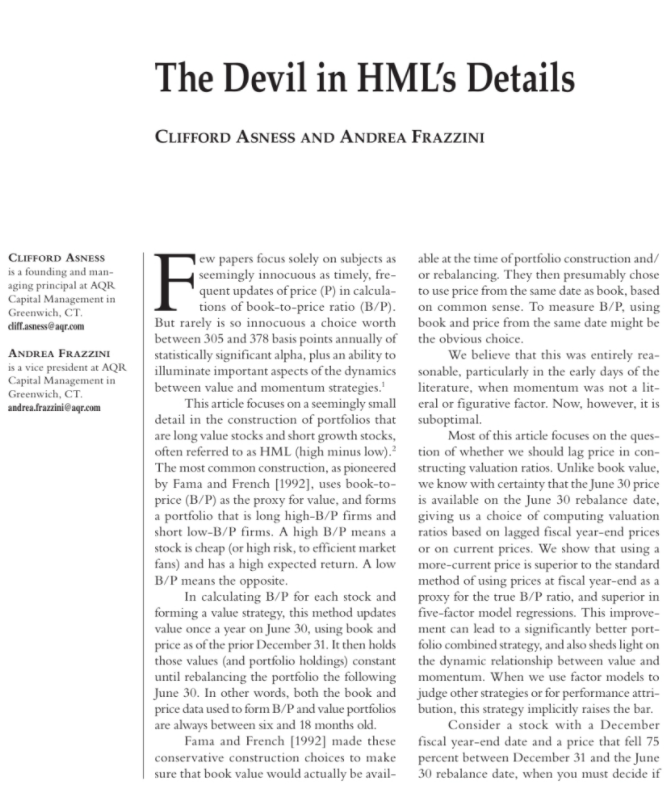

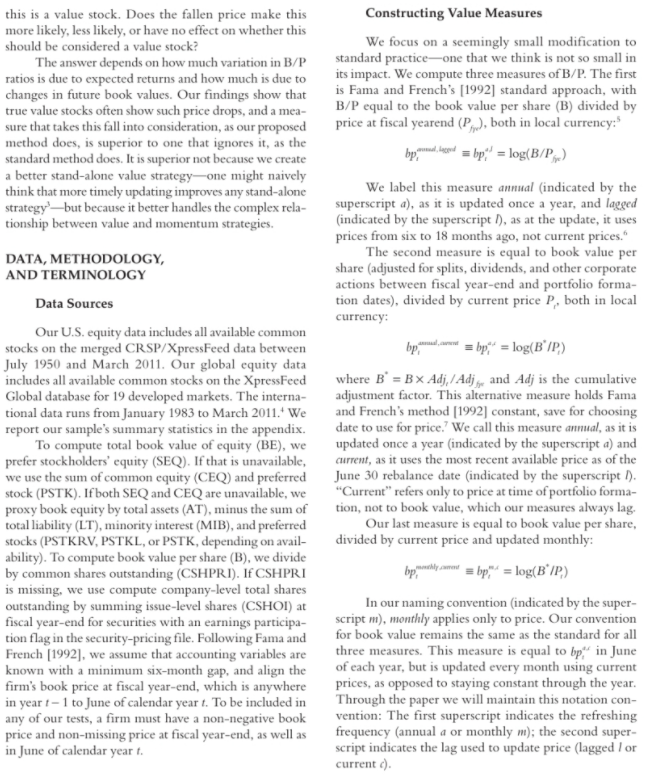

What they advocate is to use the most recent market equity observation. They have both annual and monthly-updated one, but here we'll focus on the latter:

bmAF = FillMonths(BE)./me; 

Let's compare the two now:

indBMFF = makeUnivSortInd(bmFF, 5, NYSE);
resFF = runUnivSort(ret, indBMFF, dates, me, 'weighting', 'v', ...
                                             'timePeriod', 196306, ...
                                             'plotFigure', 0);

indBMAF = makeUnivSortInd(bmAF, 5, NYSE);
resAF = runUnivSort(ret, indBMAF, dates, me, 'weighting', 'v', ...
                                             'timePeriod', 196306, ...
                                             'plotFigure', 0);

Now let's see how they do when combined with momentum:

% Create the cross-sectional rank variables
bmFF_rank = tiedrank(FillMonths(bmFF)')';
bmAF_rank = tiedrank(bmAF')';
R_rank = tiedrank(R')';


% Combine them
bmFFR = bmFF_rank + R_rank;
bmAFR = bmAF_rank + R_rank;

indBMFFR = makeUnivSortInd(bmFFR, 5, NYSE);
resFFR = runUnivSort(ret, indBMFFR, dates, me, 'weighting', 'v', ...
                                               'timePeriod', 196306, ...
                                               'plotFigure', 0);

indBMAFR = makeUnivSortInd(bmAFR, 5, NYSE);
resAFR = runUnivSort(ret, indBMAFR, dates, me, 'weighting', 'v', ...
                                               'timePeriod', 196306, ...
                                               'plotFigure', 0);

## Let's look at investment next

There are quite a few papers that propose investment-related sorting variables. We'll replicate a few of them here and compare how the investment variables do relative to each other. Let's load a bunch of stuff first:

clear
clc

load ret
load me
load dates
load nyse
load at
load capx
load ppegt
load invt
load shrout
load cfacshr
load FinFirms
load DLTT
load DLC
load NI
load DVP
load DVC
load BE

CAPX(FinFirms==1) = nan;
AT(FinFirms==1) = nan;

The first replication will be the CAPX growth variable from Anderson and Garcia-Feijoo (JF, 2006):

cegth2 = CAPX./lag(CAPX,24,nan)-1;
ind = makeUnivSortInd(-cegth2, 5);
res = runUnivSort(ret, ind, dates, me, 'timePeriod', [197606 199906]); 

Compare this with Table III, Panel C from the paper:

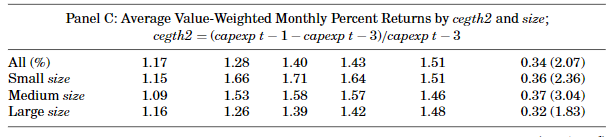

And let's also run this with a value-weighted decile NYSE break sort for the spanning tests later:

ind = makeUnivSortInd(-cegth2, 10, NYSE);
resCG = runUnivSort(ret, ind, dates, me, 'weighting', 'v', ...
                                         'timePeriod', [196306], ...
                                         'printResults', 0 ,...
                                         'plotFigure', 0); 

Next up is the asset growth effect from Cooper, Gullen, and Schill (JF, 2008):

assetGrowth = AT./lag(AT,12,nan);
ind = makeUnivSortInd(assetGrowth, 10);
res = runUnivSort(ret, ind, dates, me, 'weighting', 'e', ...
                                       'timePeriod', [196806 200306]); 

Their t-stats are outrageous, but we are not too far off:

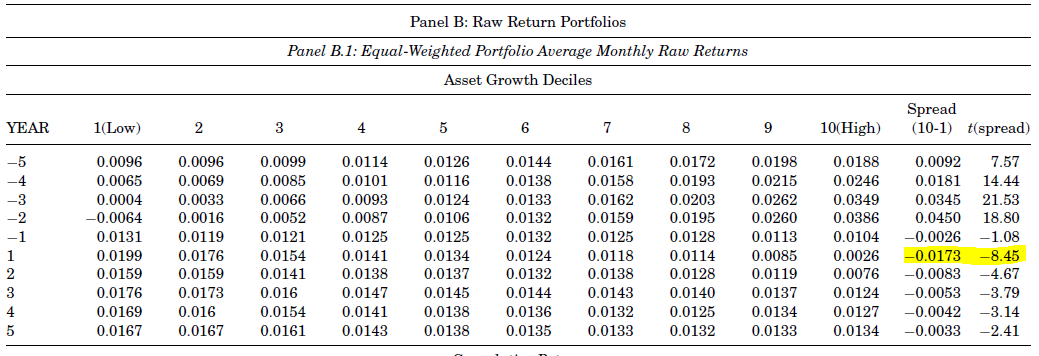

Let's again run this with a value-weighted decile NYSE break sort for the spanning tests later:

ind = makeUnivSortInd(-assetGrowth, 10, NYSE);
resAG = runUnivSort(ret, ind, dates, me, 'weighting', 'v', ...
                                         'timePeriod', [196306], ...
                                         'printResults', 0 ,...
                                         'plotFigure', 0); 

Next up, net issuance from Pontiff and Woodgate (JF, 2008). Although technically not an investment variable, it is quite closely linked with the investment effect.

ashrout = shrout.*cfacshr;
dashrout = log(ashrout ./ lag(ashrout,12,nan)); % percent change in split adjusted shares outstanding
dashrout(dates - 10*floor(dates/10) ~= 6,:) = nan;

runFamaMacBeth(100*ret,dashrout, dates, 'timePeriod', [197001 200312]); 

Compare this with the paper result:

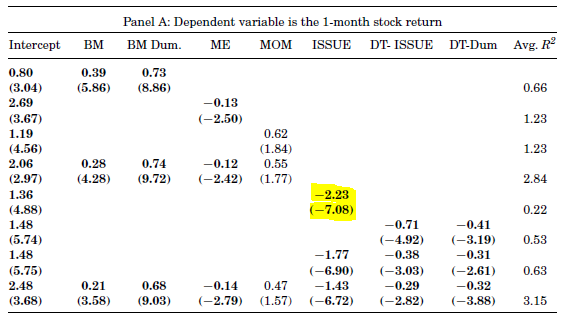

Let's again run this with a value-weighted decile NYSE break sort for the spanning tests later:

ind = makeUnivSortInd(-dashrout, 10, NYSE);
resNI = runUnivSort(ret, ind, dates, me, 'weighting', 'v', ...
                                         'timePeriod', [196306], ...
                                         'printResults', 0 ,...
                                         'plotFigure', 0); 

Next up, investment variable from Lyandres, Sun, and Zhang (RFS, 2008). They don't really report a proper sort on this. They instead construct an investor factor that is similar in spirit to the Fama-French factors, but has a more involved construction. We'll just run the value-weighted decile NYSE break sort:

investment = ( PPEGT - lag(PPEGT, 12, nan) + ...
               INVT  - lag(INVT, 12, nan)  ) ...
               ./lag(AT,12,nan);

ind = makeUnivSortInd(-investment, 10, NYSE);
resInv = runUnivSort(ret, ind, dates, me, 'weighting', 'v', ...
                                         'timePeriod', [196306], ...
                                         'printResults', 0 ,...
                                         'plotFigure', 0); 

Now let's compare the strategy returns:

retCG = resCG.pret(:,end);
retAG = resAG.pret(:,end);
retNI = resNI.pret(:,end);
retInv = resInv.pret(:,end);
dates = resInv.dates;
const = 0.01*ones(size(dates));

y = [retCG retAG retNI retInv];

corrcoef(y(2:end,:))

ibbots(y, dates, 'legendLabels', {'CAPX growth','Asset growth','Net issuance','Investment'}, ...
                 'linPlotInd', 0);

prt(nanols(retCG,  [const]))
prt(nanols(retAG,  [const]))
prt(nanols(retNI,  [const]))
prt(nanols(retInv, [const]))


And run some spanning tests:

prt(nanols(retCG,  [const retAG retNI retInv]))
prt(nanols(retAG,  [const retCG retNI retInv]))
prt(nanols(retNI,  [const retCG retAG retInv]))
prt(nanols(retInv, [const retCG retAG retNI]))

Finally, let's run some Fama-MacBeths:

runFamaMacBeth(100*ret, [cegth2],                                 dates, 'timePeriod', 196306);
runFamaMacBeth(100*ret, [assetGrowth],                            dates, 'timePeriod', 196306);
runFamaMacBeth(100*ret, [dashrout],                               dates, 'timePeriod', 196306);
runFamaMacBeth(100*ret, [investment],                             dates, 'timePeriod', 196306);
runFamaMacBeth(100*ret, [cegth2 assetGrowth dashrout investment], dates, 'timePeriod', 196306);

## Profitability is next

Similar story to investment. Quite a few papers out there. We'll look at 4 different profitability proxies:

clear
clc

load ret
load me
load dates
load nyse
load at
load FinFirms
load GP 
load bm
load REVT
load COGS
load XSGA
load XINT
load XRD
load BE
load drc
load drlt
load RECT
load RECT
load xpp
load AP
load INVT
load XACC
load BEQ
load IBQ

AT(FinFirms==1) = nan;
BE(FinFirms==1) = nan;
BEQ(FinFirms==1) = nan;

Let's start with Novy-Marx (2012) - gross profitability:

GrossProf = GP./AT;
ind = makeUnivSortInd(GrossProf, 5, NYSE);
res = runUnivSort(ret, ind, dates, me, 'weighting', 'v', ...
                                       'timePeriod', [196306 201012], ...
                                       'factorModel', 3); 

Compare with the result in the paper:

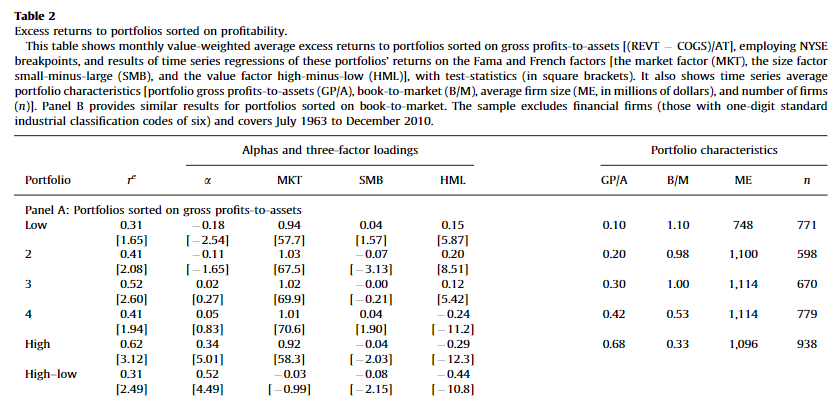

The results that sold the paper and made Robert really famous in the factor investing industry was the significantly negative loading on HML. Value and gross profitability work really well together. This led to an explosion of "quality" funds and his work was heavily used in marketing those. To see why that's important, look at the performance of value, gross profitability, and a combo of the two:

% Create the cross-sectional rank variables
gp_rank = tiedrank(GrossProf')';
bm_rank = tiedrank(bm')';

% Combine them
gp_bm = gp_rank + bm_rank;

% Sort on gross profitability
ind = makeUnivSortInd(GrossProf, 10, NYSE);
resGP = runUnivSort(ret, ind, dates, me, 'weighting', 'v', ...
                                         'timePeriod', [196306], ...
                                         'printResults', 0 ,...
                                         'plotFigure', 0); 

% Sort on book-to-market
ind = makeUnivSortInd(bm, 10, NYSE);
resBM = runUnivSort(ret, ind, dates, me, 'weighting', 'v', ...
                                         'timePeriod', [196306], ...
                                         'printResults', 0 ,...
                                         'plotFigure', 0); 

% Sort on the combined rank
ind = makeUnivSortInd(gp_bm, 10, NYSE);
resGPBM = runUnivSort(ret, ind, dates, me, 'weighting', 'v', ...
                                         'timePeriod', [196306], ...
                                         'printResults', 0 ,...
                                         'plotFigure', 0); 


retGP = resGP.pret(:, end);
retBM = resBM.pret(:, end);
retGPBM = resGPBM.pret(:, end);

ibbots([retGP retBM retGPBM], resGP.dates, 'legendLabels', {'GP','BM','GP+BM'});

Let's look at Fama and French's (2015) operating profitability:

OP = REVT + nanmatsum(-COGS, -nanmatsum(XSGA, XINT));
OpProf = OP./BE;

ind = makeBivSortInd(me, 5, OpProf, 5, 'sortType', 'unconditional', ...
                                       'breaksFilterInd', NYSE);
[res, ~] = runBivSort(ret, ind, 5, 5, dates, me, 'timePeriod', [196306 201312]);

Compare with:

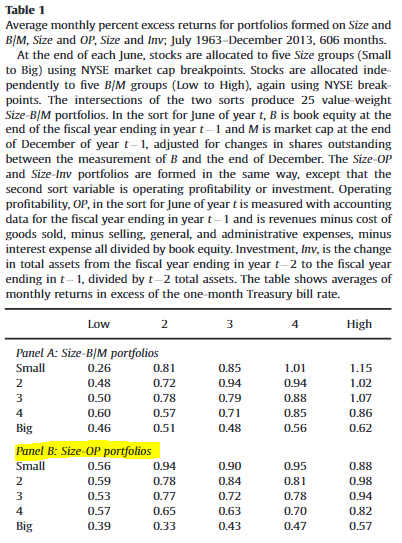

Let's again run this with a value-weighted decile NYSE break sort for the spanning tests later:

ind = makeUnivSortInd(OpProf, 10, NYSE);
resOP = runUnivSort(ret, ind, dates, me, 'weighting', 'v', ...
                                         'timePeriod', [196306], ...
                                         'printResults', 0 ,...
                                         'plotFigure', 0); 

Next up, Ball, Gerakos, Linnainmaa, and Nikolaev's (JFE, 2016) cash-based profitability:

% They start out with a slightly different operating profitability measure:
OP = REVT - nanmatsum(COGS, nanmatsum(XSGA, -XRD));

% Deferred revenue
DR = DRC + DRLT;

% Exlude zero or negative book value
BE(BE <= 0) = nan;

% Create changes in variables that enter accruals calculation
dRECT = RECT-lag(RECT,12,nan); % Receivables
dXPP  = XPP-lag(XPP,12,nan);   % Prepaid expenses
dAP   = AP-lag(AP,12,nan);     % Account payable
dINVT = INVT-lag(INVT,12,nan); % Inventories
dDR   = DR-lag(DR,12,nan);     % Deferred revenue
dXACC = XACC-lag(XACC,12,nan); % Accued expenses

% Create accruals
Accruals = nanmatsum(zeros(size(dRECT)), ... 
                     nanmatsum(dRECT,  ...
                     nanmatsum(dINVT, ...
                     nanmatsum(dXPP, ...
                     nanmatsum(-dAP, ...
                     nanmatsum(-dDR, -dXACC))))));

% Create cash-profitability
CP = OP - Accruals;

% Scale it by total assets
CashProf = CP ./ AT;

ind = makeUnivSortInd(CashProf, 10, NYSE);
res = runUnivSort(ret, ind, dates, me, 'weighting', 'v', ...
                                         'timePeriod', [196306 201412], ...
                                         'factorModel', 1, ...
                                         'printResults', 1 ,...
                                         'plotFigure', 0); 

Compare with:

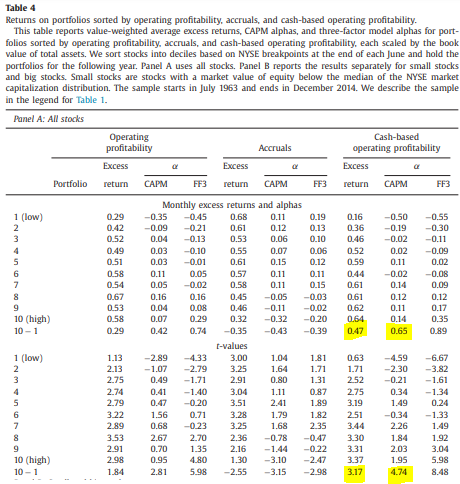

Let's again run this with a value-weighted decile NYSE break sort for the spanning tests later:

ind = makeUnivSortInd(CashProf, 10, NYSE);
resCP = runUnivSort(ret, ind, dates, me, 'weighting', 'v', ...
                                         'timePeriod', [196306], ...
                                         'printResults', 0 ,...
                                         'plotFigure', 0); 


Finally, Lu Zhang and co-authors (e.g., Hou, Xue, and Zhang, 2015) use an ROE-based profitability factor. It uses quarterly data. Let's  run this with a value-weighted decile NYSE break sort for the spanning tests later:

roe = IBQ./lag(BEQ,3,nan);
ind = makeUnivSortInd(roe, 10, NYSE);
resROE = runUnivSort(ret, ind, dates, me, 'weighting', 'v', ...
                                         'timePeriod', [196306], ...
                                         'printResults', 0 ,...
                                         'plotFigure', 0); 

Now let's compare the strategy returns:

retGP = resGP.pret(:,end);
retOP = resOP.pret(:,end);
retCP = resCP.pret(:,end);
retROE = resROE.pret(:,end);
dates = resROE.dates;
const = 0.01*ones(size(dates));

y = [retGP retOP retCP retROE];

corrcoef(y(2:end,:))

ibbots(y, dates, 'timePeriod', 197501, 'legendLabels', {'Gross prof','Operating prof','Cash-based prof','ROE'});

prt(nanols(retGP,  [const]))
prt(nanols(retOP,  [const]))
prt(nanols(retCP,  [const]))
prt(nanols(retROE, [const]))


And run some spanning tests:

prt(nanols(retGP,  [const retOP retCP retROE]))
prt(nanols(retOP,  [const retGP retCP retROE]))
prt(nanols(retCP,  [const retGP retOP retROE]))
prt(nanols(retROE, [const retGP retOP retCP]))

Finally, let's run some Fama-MacBeths:

runFamaMacBeth(100*ret, [GrossProf],                     dates, 'timePeriod', 196306);
runFamaMacBeth(100*ret, [OpProf],                        dates, 'timePeriod', 196306);
runFamaMacBeth(100*ret, [CashProf],                      dates, 'timePeriod', 196306);
runFamaMacBeth(100*ret, [roe],                           dates, 'timePeriod', 197306);
runFamaMacBeth(100*ret, [GrossProf OpProf CashProf roe], dates, 'timePeriod', 197306);